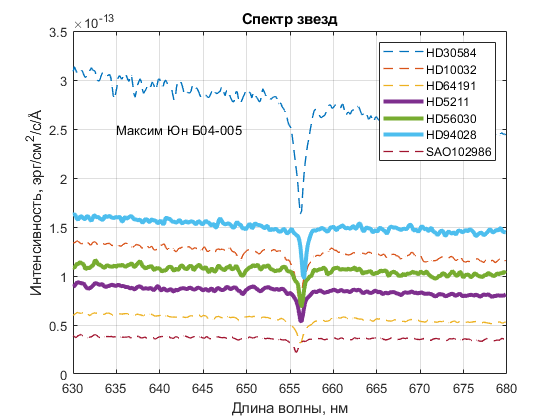

spectra=importdata("spectra.csv");
lambdaStart=importdata("lambda_start.csv");
lambdaDelta=importdata("lambda_delta.csv");
starNames=importdata("star_names.csv");
[vichisl N]=size(spectra);
LambdaPr=656.28;
speedOfLight=299792.458;
lambdaEnd=lambdaStart+(vichisl-1)*lambdaDelta;
lambda=(lambdaStart: lambdaDelta: lambdaEnd)';
f1=figure;
speed=zeros(1,N);
for i=1:1:N 
    s=spectra(:,i);
    [sHa, index] = min(s);
    lambdaHa=lambda(index);
    z=(lambdaHa/LambdaPr)-1;
    speed(1,i)=z*speedOfLight;
end
for i =1:1:N
    s=spectra(:,i);
    if speed(1,i)<0
        plot(lambda,s, '--','LineWidth',1)
    else
        plot(lambda,s,'LineWidth',3)
    end
    hold on
end
hold off
grid("on")
set(f1, 'Visible','on')
xlabel('Длина волны, нм')
ylabel(['Интенсивность, эрг/см^2/с/',char(197)])
title('Спектр звезд')
legend(starNames)
text(635,2.5*10^-13,'Максим Юн Б04-005')

saveas(f1,'spectra.png','png')